# Dynamics Homework ? Question ?

% Problem
clc
clearvars

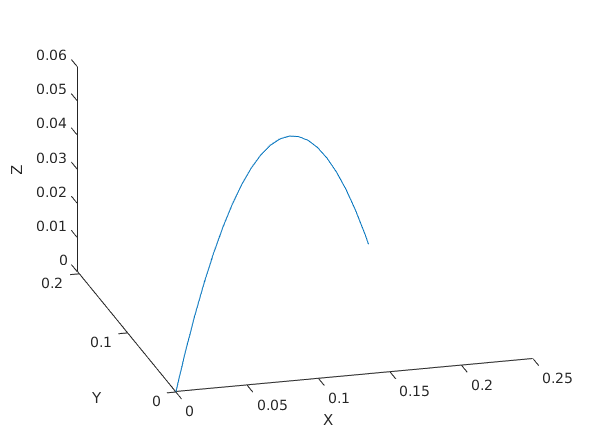

% initial position
x0 = 0;
y0 = 0;
z0 = 0;

% initial velocity
dx = 1;
dy = 1;
dz = 1;

% pack initial conditions into column vector
init = [x0 dx y0 dy z0 dz]';

% run simulation
[t,p] = simulation(init);

% plotting
x = p(:,1);
y = p(:,3);
z = p(:,5);

figure
plot3(x,y,z)
xlabel("X")
ylabel("Y")
zlabel("Z")

function [t,p] = simulation(init)
    
    % time span
    tspan = [0:.01:1];
    
    % simulation params, used in ODE funcs
    g = 9.8;
    
    % use ode45 and stop at event
    options = odeset('Events', @eventFcn);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        dx = p(2);  % x velocity
        ddx = 0;    % x accel
        dy = p(4);  % y velocity
        ddy = 0;    % y accel
        dz = p(6);  % z velocity
        ddz = -g;   % z accel
        
        % pack ODEs into column vector
        dpdt = [dx ddx dy ddy dz ddz]';
    end
    
    function [position,isterminal,direction] = eventFcn(~,p)
        position = p(5); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end